Part 1: Finding gain and intercepts for uncontrolled system.


p = [0.0001 0.0009 0.0818 0.4133 0.8067 0.6053 -0.0206];
z = [1.709e-6 7.919e-6 9.091e-6];

a=-0.0001;
b=0.0009;
c=0.0818;
d=-0.4133;
e=-0.8067;
f=0.6053;
g=-0.0206;
h=-1.709e-6;
j=7.919e-6;
k=9.091e-6;

one=a-((h*b)/j);
two=c-(((k*b)+(h*d))/j);
three=e-(((k*d)+(f*h))/j);
four=g-(f*k/j);
equation= [one 0 two 0 three 0 four];
eqution=roots(equation)

eqution =  -10.4686 + 0.0000i
  10.4686 + 0.0000i
  -0.0000 + 3.9696i
  -0.0000 - 3.9696i
  -0.0000 + 2.0969i
  -0.0000 - 2.0969i


w=-10.4686

w = -10.4686

K=(1/-j)*((b*(w^4))+(d*(w^2))+(f))

K = 4.2783e+06

Part 2: Root Locus Plots

%Original Root Locus
s = tf('s');
GH = ((1.706e-6*s^2 + 7.919e-6*s + 9.091e-06))/((0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206))

GH =
 
                       1.706e-06 s^2 + 7.919e-06 s + 9.091e-06
  ----------------------------------------------------------------------------------
  0.0001 s^6 + 0.0009 s^5 + 0.0818 s^4 + 0.4133 s^3 + 0.8067 s^2 + 0.6053 s - 0.0206
 
Continuous-time transfer function.
Model Properties


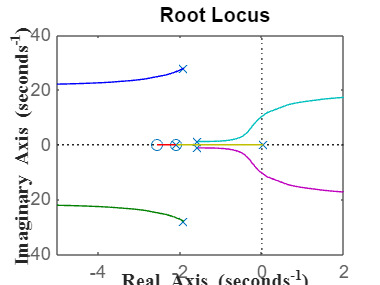

rlocus(GH)
xlim([-5 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')

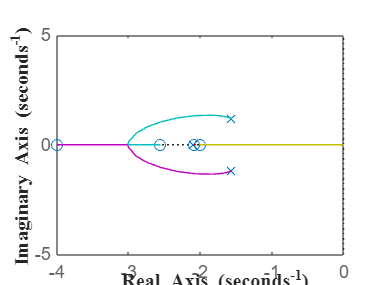



%Using variables to calculate new root locus with 3 new zeroes 
a=1.706e-6;
b=7.919e-6;
c=9.091e-06;
d=6;
e=8;
f=4;

four=a;
three=b+(d*a);
two=c+(d*b)+(a*e);
one=(d*c)+(e*b);
zero=c*e;

b1=a;
b2=three+(f*a);
b3=two+(f*three);
b4=one+(f*two);
b5=zero+(f*one);
b6=f*zero;

% Plotting damping ratios 0.7, 0.8 and 0.9
x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[]; 

p=0;

for n=2:-1:-60
    p=p+1;
    x1(p)=n;
    x2(p)=n;
    x3(p)=n;
    x4(p)=n;
    y1(p)=n/-0.7;
    y2(p)=n/-0.8;
    y3(p)=n/-0.9;
    y4(p)=(0.4871*n)+36.057;
end

%Combining root locus with intersecting lines
G2=((b1*s^5+b2*s^4+b3*s^3+b4*s^2+b5*s+b6))/(0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206);
rlocus(G2)  
xlim([-4 0])
ylim([-5 5])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')

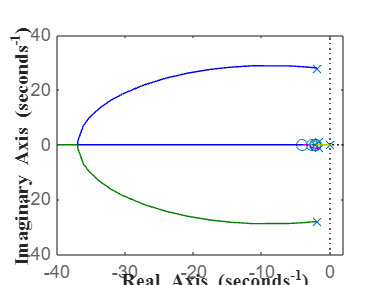


G2=((b1*s^5+b2*s^4+b3*s^3+b4*s^2+b5*s+b6))/(0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206);
rlocus(G2)  
xlim([-40 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')

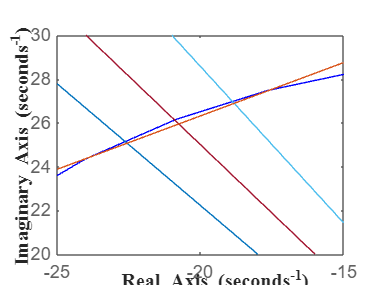


G2=((b1*s^5+b2*s^4+b3*s^3+b4*s^2+b5*s+b6))/(0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206);
rlocus(G2)  
hold on
plot(x1,y1,x2,y2,x3,y3,x4,y4)
xlim([-25 -15])
ylim([20 30])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')
hold off


G2=((b1*s^5+b2*s^4+b3*s^3+b4*s^2+b5*s+b6))/(0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206)

G2 =
 
  1.706e-06 s^5 + 2.498e-05 s^4 + 0.0001429 s^3 + 0.0003989 s^2 + 0.0005443 s + 0.0002909
  ---------------------------------------------------------------------------------------
    0.0001 s^6 + 0.0009 s^5 + 0.0818 s^4 + 0.4133 s^3 + 0.8067 s^2 + 0.6053 s - 0.0206
 
Continuous-time transfer function.
<a href="matlab:disp(char('','       Numerator: {[0 1.7060e-06 2.4979e-05 1.4287e-04 3.9891e-04 5.4432e-04 2.9091e-04]} ','     Denominator: {[1.0000e-04 9.0000e-04 0.0818 0.4133 0.8067 0.6053 -0.0206]} ','        Variable: ''s'' ','         IODelay: [0] ','      InputDelay: [0] ','     OutputDelay: [0] ','       InputName: {''''} ','       InputUnit: {''''} ','      InputGroup: [1×1 struct] ','      OutputName: {''''} ','      OutputUnit: {''''} ','     OutputGroup: [1×1 struct] ','           Notes: [0×1 string] ','        UserData: [] ','            Name: '''' ','              Ts: [0] ','        TimeUnit: ''seconds'' ','    SamplingGrid: [1×1 struct] ',' '))">Model Properties</a

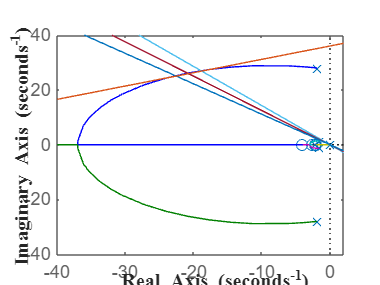

rlocus(G2)  
hold on
plot(x1,y1,x2,y2,x3,y3,x4,y4)
xlim([-40 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')
hold off


%Determining value of gain at intersection 
G2_f= @(s) (0.0001*s.^6 + 0.0009*s.^5 + 0.0818*s.^4 + 0.4133*s.^3 + 0.8067*s.^2 + 0.6053*s - 0.0206)/(b1*s.^5+b2*s.^4+b3*s.^3+b4*s.^2+b5*s+b6);
s=-18.82+26.89i % The value of s changes depending on what point you use

s = -18.8200 +26.8900i

disp(G2_f(s))

  -2.0349e+03 - 1.6463e+01i




%Test examples
s = tf('s');

a=(s+1)

a =
 
  s + 1
 
Continuous-time transfer function.
Model Properties


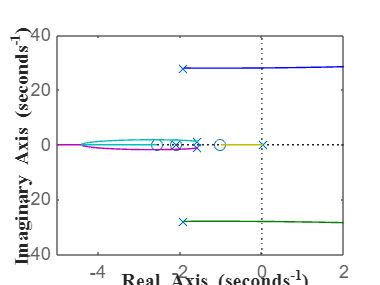

sys = ((1.706e-6*s^2 + 7.919e-6*s + 9.091e-06)*a)/((0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206));
rlocus(sys)
xlim([-5 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')


a=(s^2+10.6)

a =
 
  s^2 + 10.6
 
Continuous-time transfer function.
Model Properties


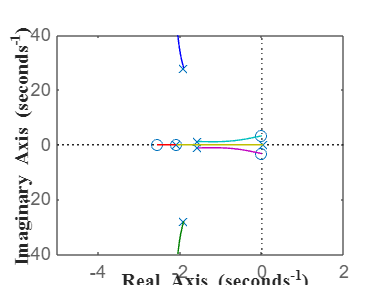

sys = ((1.706e-6*s^2 + 7.919e-6*s + 9.091e-06)*a)/((0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206));
rlocus(sys)
xlim([-5 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')


a=(s^2+10*s+14)

a =
 
  s^2 + 10 s + 14
 
Continuous-time transfer function.
Model Properties


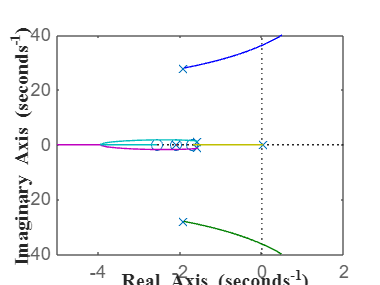

sys = ((1.706e-6*s^2 + 7.919e-6*s + 9.091e-06)*a)/((0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206));
rlocus(sys)
xlim([-5 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')


a=(s^2+6*s + 100)*(s+5)

a =
 
  s^3 + 11 s^2 + 130 s + 500
 
Continuous-time transfer function.
Model Properties


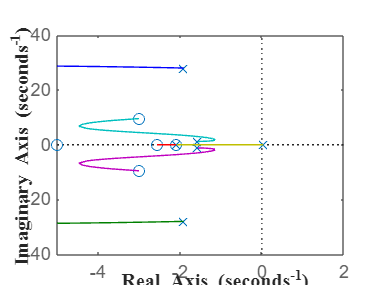

sys = ((1.706e-6*s^2 + 7.919e-6*s + 9.091e-06)*a)/((0.0001*s^6 + 0.0009*s^5 + 0.0818*s^4 + 0.4133*s^3 + 0.8067*s^2 + 0.6053*s - 0.0206));
rlocus(sys)
xlim([-5 2])
ylim([-40 40])
ylabel('Imaginary Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
xlabel('Real Axis', 'FontSize', 11, 'FontName','Times New Roman','FontWeight','bold')
title('')